clear;clc; close all;
%%参数设置
c=3e8;%光速
f0=5.321e9;%载频
dFs=[20e6,10e6];%频率步进值
Ns=[21,41];%子脉冲个数
n=2;%选择仿真参数
dF=dFs(n);N=Ns(n);%变量赋值
B=(N-1)*dF;%合成带宽
Tp=6e-6;%单个脉冲信号持续时间
fs=6*B;%设置采样率
Ts=1/fs;%采样间隔
Tr=Tp*2;%脉冲重复时间间隔
num=round(N*Tr/Ts);%采样点数
%%设置目标参数
R=[995,1000,1001,1005];%目标距离
RCS=[1 1.5 2.25 3.375];%目标有效面积（反射系数）
R=[1000];%目标距离
RCS=[1.5];%目标有效面积（反射系数）
M=length(R);%目标个数
Ru=c/2/dF;%最大不模糊距离
R0=mean(R);%设置参考中心距离（用于保证目标在一个回波探测范围内
Rmax=floor(R0+Ru/2);%观察目标距离雷达的最远距离
Rmin=floor(R0-Ru/2);%观察目标距离雷达的最近距离

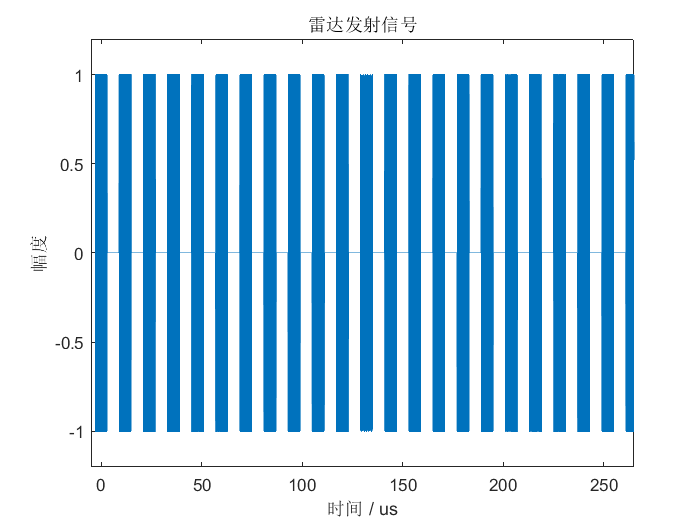

%% 频率步进信号
t0=linspace(-Tp/2,Tp/2+(N-1)*Tr,num);%时间
index=floor((t0+Tp/2)/Tr);%子脉冲序号，从0开始
St=exp(2*j*pi*(f0+index.*dF).*t0).*rectpuls((t0-index*Tr)/Tp);%发射的SFCW信号
%% 绘图
figure,plot(t0*1e6,real(St));axis tight
xlabel('时间 / us');ylabel("幅度");title("雷达发射信号")
axis([-5,265,-1.2*max(real(St)),1.2*max(real(St))]);

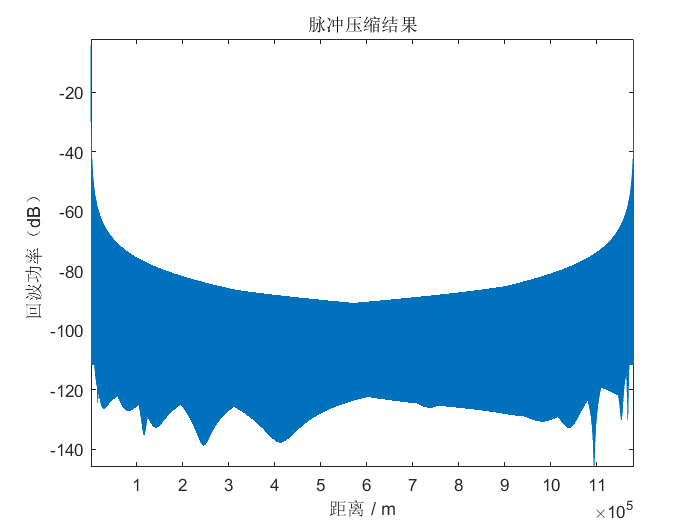

%%基带回波频域
tao=2*R'/c*ones(1,num);%回波时间
Sfk=RCS*(exp(-2*j*pi*(index.*dF).*tao) );
figure,plot(real(db(ifft(Sfk))));axis tight
xlabel('距离 / m');ylabel("回波功率（dB）");title("脉冲压缩结果")